# Macro III: Problem Set 3

Deadline: Monday, 08/10/2018

Aluno: Bruno Tebaldi de Queiroz Barbosa (C174887)

Professor: Tiago Cavalcanti

Source code disponível em: [https://github.com/btebaldi/Macro3/tree/master/PSet_04](https://github.com/btebaldi/Macro3/tree/master/PSet_02)

Script construido baseado nos scripts de B.Moll

Fonte original em: [http://www.princeton.edu/~moll/HACTproject.htm](http://www.princeton.edu/~moll/HACTproject.htm)

## Questão 4

% limpa variaveis
clear all;
clc;

% fecha eventuais janelas abertas
close all;

% inicia o cronometro
tic;

% define variaveis
ga = 2;
rho = 0.05;
d = 0.05;
al = 1/3;
Aprod = 0.1;
z1 = 1;
z2 = 2*z1;
z = [z1,z2];
la1 = 1/3;
la2 = 1/3;
la = [la1,la2];
z_ave = (z1*la2 + z2*la1)/(la1 + la2);

I= 1000;
amin = 0;
amax = 20;
a = linspace(amin,amax,I)';
da = (amax-amin)/(I-1);

aa = [a,a];
zz = ones(I,1)*z;


maxit= 100;
crit = 10^(-6);
Delta = 1000;

dVf = zeros(I,2);
dVb = zeros(I,2);
c = zeros(I,2);

Aswitch = [-speye(I)*la(1),speye(I)*la(1);speye(I)*la(2),-speye(I)*la(2)];

Ir = 40;
crit_S = 10^(-5);


rmax = 0.049;
r = 0.04;
w = 0.05;

r0 = 0.03;
rmin = 0.01;
rmax = 0.99*rho;


for ir=1:Ir;

r_r(ir)=r;
rmin_r(ir)=rmin;
rmax_r(ir)=rmax;

KD(ir) = (al*Aprod/(r + d))^(1/(1-al))*z_ave;
w = (1-al)*Aprod*KD(ir).^al*z_ave^(-al);

if w*z(1) + r*amin < 0
    disp('CAREFUL: borrowing constraint too loose')
end

v0(:,1) = (w*z(1) + r.*a).^(1-ga)/(1-ga)/rho;
v0(:,2) = (w*z(2) + r.*a).^(1-ga)/(1-ga)/rho;

if ir>1
v0 = V_r(:,:,ir-1);
end

v = v0;

for n=1:maxit
    V = v;
    V_n(:,:,n)=V;
    % forward difference
    dVf(1:I-1,:) = (V(2:I,:)-V(1:I-1,:))/da;
    dVf(I,:) = (w*z + r.*amax).^(-ga); %will never be used, but impose state constraint a<=amax just in case
    % backward difference
    dVb(2:I,:) = (V(2:I,:)-V(1:I-1,:))/da;
    dVb(1,:) = (w*z + r.*amin).^(-ga); %state constraint boundary condition
    
    %consumption and savings with forward difference
    cf = dVf.^(-1/ga);
    ssf = w*zz + r.*aa - cf;
    %consumption and savings with backward difference
    cb = dVb.^(-1/ga);
    ssb = w*zz + r.*aa - cb;
    %consumption and derivative of value function at steady state
    c0 = w*zz + r.*aa;
    
    % dV_upwind makes a choice of forward or backward differences based on
    % the sign of the drift    
    If = ssf > 0; %positive drift --> forward difference
    Ib = ssb < 0; %negative drift --> backward difference
    I0 = (1-If-Ib); %at steady state
    
    c = cf.*If + cb.*Ib + c0.*I0;
    u = c.^(1-ga)/(1-ga);
    
    %CONSTRUCT MATRIX
    X = -min(ssb,0)/da;
    Y = -max(ssf,0)/da + min(ssb,0)/da;
    Z = max(ssf,0)/da;
    
    A1=spdiags(Y(:,1),0,I,I)+spdiags(X(2:I,1),-1,I,I)+spdiags([0;Z(1:I-1,1)],1,I,I);
    A2=spdiags(Y(:,2),0,I,I)+spdiags(X(2:I,2),-1,I,I)+spdiags([0;Z(1:I-1,2)],1,I,I);
    A = [A1,sparse(I,I);sparse(I,I),A2] + Aswitch;
    
    if max(abs(sum(A,2)))>10^(-9)
       disp('Improper Transition Matrix')
       %break
    end
    
    B = (1/Delta + rho)*speye(2*I) - A;

    u_stacked = [u(:,1);u(:,2)];
    V_stacked = [V(:,1);V(:,2)];
    
    b = u_stacked + V_stacked/Delta;
    V_stacked = B\b; %SOLVE SYSTEM OF EQUATIONS
    
    V = [V_stacked(1:I),V_stacked(I+1:2*I)];
    
    Vchange = V - v;
    v = V;

    dist(n) = max(max(abs(Vchange)));
    if dist(n)<crit
        fprintf('Value Function Converged, Iteration = %d\n', n)
        break
    end
end
toc;

%%%%%%%%%%%%%%%%%%%%%%%%%%
% FOKKER-PLANCK EQUATION %
%%%%%%%%%%%%%%%%%%%%%%%%%%
AT = A';
b = zeros(2*I,1);

%need to fix one value, otherwise matrix is singular
i_fix = 1;
b(i_fix)=.1;
row = [zeros(1,i_fix-1),1,zeros(1,2*I-i_fix)];
AT(i_fix,:) = row;

%Solve linear system
gg = AT\b;
g_sum = gg'*ones(2*I,1)*da;
gg = gg./g_sum;

g = [gg(1:I),gg(I+1:2*I)];

check1 = g(:,1)'*ones(I,1)*da;
check2 = g(:,2)'*ones(I,1)*da;

g_r(:,:,ir) = g;
adot(:,:,ir) = w*zz + r.*aa - c;
V_r(:,:,ir) = V;

KS(ir) = g(:,1)'*a*da + g(:,2)'*a*da;
S(ir) = KS(ir) - KD(ir);

%UPDATE INTEREST RATE
if S(ir)>crit_S
    disp('Excess Supply')
    rmax = r;
    r = 0.5*(r+rmin);
elseif S(ir)<-crit_S;
    disp('Excess Demand')
    rmin = r;
    r = 0.5*(r+rmax);
elseif abs(S(ir))<crit_S;
    fprintf('Equilibrium Found, Interest rate = %f\n', r)
    break
end

end

Value Function Converged, Iteration = 7


Elapsed time is 0.680322 seconds.


Excess Demand


Value Function Converged, Iteration = 6


Elapsed time is 0.722237 seconds.


Excess Demand


Value Function Converged, Iteration = 5


Elapsed time is 0.771103 seconds.


Excess Supply


Value Function Converged, Iteration = 5


Elapsed time is 0.805085 seconds.


Excess Supply


Value Function Converged, Iteration = 5


Elapsed time is 0.838482 seconds.


Excess Supply


Value Function Converged, Iteration = 5


Elapsed time is 0.875573 seconds.


Excess Supply


Value Function Converged, Iteration = 5


Elapsed time is 0.900141 seconds.


Excess Demand


Value Function Converged, Iteration = 4


Elapsed time is 0.928694 seconds.


Excess Demand


Value Function Converged, Iteration = 4


Elapsed time is 0.955599 seconds.


Excess Supply


Value Function Converged, Iteration = 4


Elapsed time is 0.977354 seconds.


Excess Demand


Value Function Converged, Iteration = 4


Elapsed time is 0.999532 seconds.


Excess Supply


Value Function Converged, Iteration = 4


Elapsed time is 1.025308 seconds.


Excess Supply


Value Function Converged, Iteration = 4


Elapsed time is 1.051013 seconds.


Excess Supply


Value Function Converged, Iteration = 3


Elapsed time is 1.076275 seconds.


Excess Supply


Value Function Converged, Iteration = 3


Elapsed time is 1.098829 seconds.


Excess Demand


Value Function Converged, Iteration = 3


Elapsed time is 1.122672 seconds.


Equilibrium Found, Interest rate = 0.044992



amax1 = 5;
amin1 = amin-0.1;

figure(1)
h1 = plot(a,adot(:,1,ir),'b',a,adot(:,2,ir),'r',linspace(amin1,amax1,I),zeros(1,I),'k--','LineWidth',2);
legend(h1,'s_1(a)','s_2(a)','Location','NorthEast');

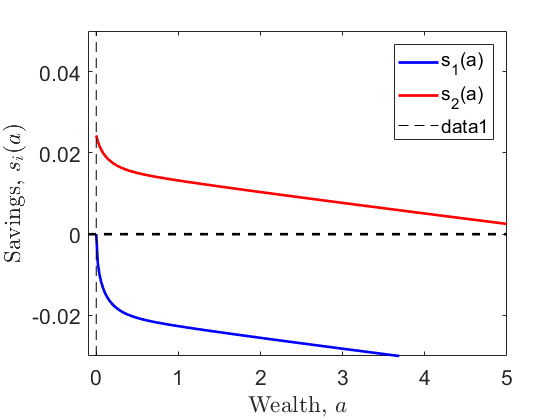

text(-0.155,-.105,'$\underline{a}$','FontSize',16,'interpreter','latex');
line([amin amin], [-.1 .08],'Color','Black','LineStyle','--');
xlabel('Wealth, $a$','interpreter','latex');
ylabel('Savings, $s_i(a)$','interpreter','latex');
xlim([amin1 amax1]);
ylim([-0.03 0.05]);
set(gca,'FontSize',16);

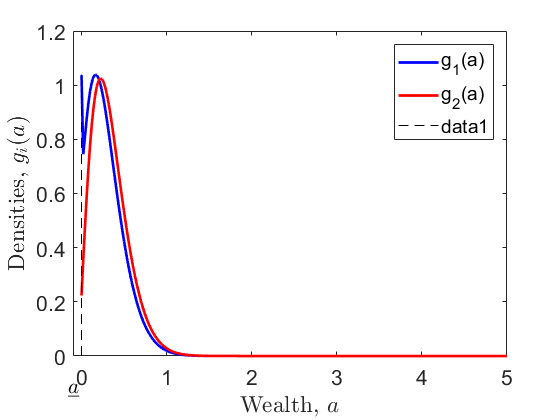


figure(2)
h1 = plot(a,g_r(:,1,ir),'b',a,g_r(:,2,ir),'r','LineWidth',2);
legend(h1,'g_1(a)','g_2(a)');
text(-0.155,-.12,'$\underline{a}$','FontSize',16,'interpreter','latex');
line([amin amin], [0 max(max(g_r(:,:,ir)))],'Color','Black','LineStyle','--');
xlabel('Wealth, $a$','interpreter','latex');
ylabel('Densities, $g_i(a)$','interpreter','latex');
xlim([amin1 amax1]);
%ylim([0 0.5])
set(gca,'FontSize',16);